# Electric field of optical fiber taper - HE11 mode

close all


## Input

data = [0.75e-6, 1.1387, 8.7144e-07;
        1.0e-6, 1.2246, 9.7777e-07; % 1.2246 (Sjoerd) 1.22155699 (Bradley)
        1.25e-6, 1.2805, 1.1661e-06; % 1.2805 (Sjoerd)
        1.5e-6, 1.3163, 1.3357e-06;
        1.75e-6, 1.3437, 1.5298e-06;
        2.0e-6, 1.3636, 1.7298e-06];

% Select taper diameter (micron)
diam =1*1e-6;                   

% Input power (W)
P = 1.0;                     


## Parameters

data_idx = find(ismembertol(data(:,1), diam, 1e-7), 1, 'first');
n_eff = data(data_idx, 2);      % Effective refractive index
MFD = data(data_idx, 3);        % Mode field diameter (m)
lambda = 1.55e-6;               % Wavelength (m)
k0 = 2 * pi / lambda;           % Free-space wavenumber
n2 = 1.444;                     % Cladding refractive index
n3 = 1.0;                       % Surrounding refractive index 
eps0 = 8.8542e-12;              % Free-space permittivity

b = diam / 2;                   % Cladding radius (m)
a = b / 15.24;                  % Core radius (m) 
beta = k0 * n_eff;              % Propagation constant: k0 * n_eff

v = 1;                          % Mode order = 1 for HE11

% Core field amplitude
I = 4 * P / (pi * MFD^2);                   % (W/m^2) Laser intensity
E0 = sqrt(2 * I / (3e8 * n_eff * eps0));    % (V/m) Electric field amplitude
                                
% Derived quantities
U = b * sqrt(k0^2 * n2^2 - beta^2);         % Core wavenumber 
W = b * sqrt(beta^2 - k0^2 * n3^2);         % Cladding decay constant  
V = 2*pi * b/lambda * sqrt(n2^2 - n3^2);    % Cladding fiber parameter 

% Bessel coefficients
b1 = 1/(2*U*besselj(v,U)) * (besselj(v-1,U) - besselj(v+1,U));
b2 = -1/(2*W*besselk(v,W)) * (besselk(v-1,W) + besselk(v+1,W));
F2 = (V/(U*W))^2 * v/(b1 + b2);
a1 = (F2 - 1)/2;
a2 = (F2 + 1)/2;

% Initialize 2D amplitude map of field
grid_size = sqrt(2) * MFD;      % Evaluate at 4 * sigma        
resolution = 1000;              
x = linspace(-grid_size, grid_size, resolution);
y = linspace(-grid_size, grid_size, resolution);
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
Phi = atan2(Y, X);

% Initialize 2D field array
E_r_2D = zeros(size(R));
E_phi_2D = zeros(size(R));
E_z_2D = zeros(size(R));

## Fields

% Cladding field
clad_idx = (R <= b);
E_r_2D(clad_idx) = -1 / besselj(v, U) * ...
    (a1 * besselj(v-1, U * R(clad_idx) / b) + ...
     a2 * besselj(v+1, U * R(clad_idx) / b)) .* cos(v * Phi(clad_idx));
E_phi_2D(clad_idx) = -1 / besselj(v, U) * ...
    (a1 * besselj(v-1, U * R(clad_idx) / b) - ...
     a2 * besselj(v+1, U * R(clad_idx) / b)) .* -sin(v * Phi(clad_idx));
E_z_2D(clad_idx) = -1j * U/(b*beta) * besselj(v, U * R(clad_idx) / b) / ...
    besselj(v,U) .* cos(v * Phi(clad_idx));

% Evanescent field 
ev_idx = (R > b);
E_r_2D(ev_idx) = -U / (W * besselk(v, W)) * ...
    (a1 * besselk(v-1, W * R(ev_idx) / b) - ...
     a2 * besselk(v+1, W * R(ev_idx) / b)) .* cos(v * Phi(ev_idx));
E_phi_2D(ev_idx) = -U / (W * besselk(v, W)) * ...
    (a1 * besselk(v-1, W * R(ev_idx) / b) + ...
     a2 * besselk(v+1, W * R(ev_idx) / b)) .* -sin(v * Phi(ev_idx));
E_z_2D(ev_idx) = -1j * U/(b*beta) * besselk(v, W * R(ev_idx) / b) / ...
    besselk(v,W) .* cos(v * Phi(ev_idx));

% Total field vector
E_vec = cat(3, E_r_2D, E_phi_2D, E_z_2D);
E_vec_cart = cat(3, ...
    E_r_2D .* cos(Phi) - E_phi_2D .* sin(Phi), ... 
    E_r_2D .* sin(Phi) + E_phi_2D .* cos(Phi), ...
    E_z_2D);


## Amplitude/Power matching

% % Integration step sizes
% dr = grid_size * 2 / resolution;  
% dphi = 2 * pi / resolution;  
% 
% dx = dr;  
% dy = R .* dphi;  
% 
% % Power density (W/m²)
% S = (beta / (2 * omega * mu_0)) * sum(E_vec.^2, 3);  
% S_cart = (beta / (2 * omega * mu_0)) * sum(E_vec_cart.^2, 3);  
% 
% % Total power before scaling
% P_total = real(sum(sum(S .* R .* dr .* dphi)));
% P_total_cart = real(sum(sum(S_cart .* dx .* dy)));
% disp(['Input power: ', num2str(P), ' W']);
% disp(['Calculated power before scaling: ', num2str(P_total_cart), ' W']);
% 
% % % Scale total E-field according to power-matching
% % E_vec = E_vec * sqrt(P / P_total);
% % E_vec_cart = E_vec_cart * sqrt(P / P_total_cart);
% 
% % Scale total E-field according to amplitude-matching
% E_vec = E_vec / max(E_vec(:)) * A;
% E_vec_cart = E_vec_cart / max(E_vec_cart(:)) * A;
% 
% % New power density (W/m²)
% S = (beta / (2 * omega * mu_0)) * sum(E_vec.^2, 3);  
% S_cart = (beta / (2 * omega * mu_0)) * sum(E_vec_cart.^2, 3);  
% 
% % Total power after scaling
% P_total = real(sum(sum(S .* R .* dr .* dphi)));
% P_total_cart = real(sum(sum(S_cart .* dx .* dy)));
% disp(['Calculated power after scaling: ', num2str(P_total_cart), ' W']);

% Field magnitudes
E_mag = sqrt(sum(E_vec.^2, 3));
E_mag_cart = sqrt(sum(E_vec_cart.^2, 3));

% Normalize total E-field
E_vec = E_vec / max(E_mag(:));
E_vec_cart = E_vec_cart / max(E_mag_cart(:));

% % Scale total E-field with amplitude from input power
% E_vec = E_vec * E0;
% E_vec_cart = E_vec_cart * E0;

% Recompute (component) magnitudes
E_mag = sqrt(sum(E_vec.^2, 3));
E_mag_cart = sqrt(sum(E_vec_cart.^2, 3));

E_r = E_vec(:,:,1);
E_phi = E_vec(:,:,2);
E_z = imag(E_vec(:,:,3));

E_x = E_vec_cart(:,:,1);
E_y = E_vec_cart(:,:,2);
E_t = sqrt(E_vec(:,:,1).^2 + E_vec(:,:,2).^2);

disp(['Peak amplitude: ', num2str(max(E_mag(:))),' V/m']);

Peak amplitude: 1 V/m


## 2D Plot

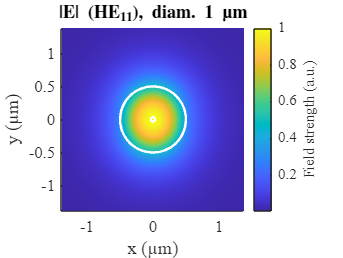

figure; hold on; box on;
imagesc(x * 1e6, y * 1e6, E_mag);  
viscircles([0, 0] * 1e6, a * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show core 
viscircles([0, 0] * 1e6, b * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show cladding
axis equal tight;
pbaspect([1 1 1]);
colormap default;
color=colorbar;
color.Label.String = 'Field strength (a.u.)';
title(['|E| (HE_{11}), diam. ',num2str(2*b*1e6),' µm']);
xlabel('x (µm)');
ylabel('y (µm)');

% Fonts to match LaTeX
set(gca, 'FontName', 'mlmodern', 'FontSize', 10);

hold off;


% matlab2tikz('D:\Documents\Study\Graduation project\MATLAB\Export\Fiber_E_1um_norm.tex',...
%     'relativeDataPath', 'Figures','showInfo', false,...
%     'extraAxisOptions', {'width=\linewidth','axis equal image'});

## 1D Slices

% % Extract 1D slice from 2D grid (y = 0)
% y_idx = round(resolution / 2);  % Middle row corresponds to y = 0
% E_r_slice = E_r(y_idx, :);
% E_phi_slice = E_phi(:, y_idx);
% E_z_slice = E_z(y_idx, :);
% 
% E_t_slice = E_t(y_idx, :);
% E_mag_slice = E_mag(y_idx, :);
% E_mag_cart_slice = E_mag_cart(y_idx, :);
% 
% % Plot 
% figure; hold on
% plot(x * 1e6, E_r_slice, 'r', 'LineWidth', 2); 
% plot(x * 1e6, E_phi_slice, 'g', 'LineWidth', 2);
% plot(x * 1e6, E_z_slice, 'b', 'LineWidth', 2);
% xline([-b*1e6 -a*1e6 a*1e6 b*1e6],'--');
% title('1D Slices');
% xlabel('Radial distance (\mum)');
% ylabel('Field strength (V/m)');
% legend('E_r', 'E_\phi', 'E_z');
% grid on;
% 
% figure; hold on
% plot(x * 1e6, E_z_slice, 'r', 'LineWidth', 2); 
% xline([-b*1e6 -a*1e6 a*1e6 b*1e6],'--');
% title(['|E| (HE11), diam. ',num2str(2*b*1e6),' \mum']);
% xlabel('Radial distance (\mum)');
% ylabel('Field strength (V/m)');
% grid on;

drawnow;
